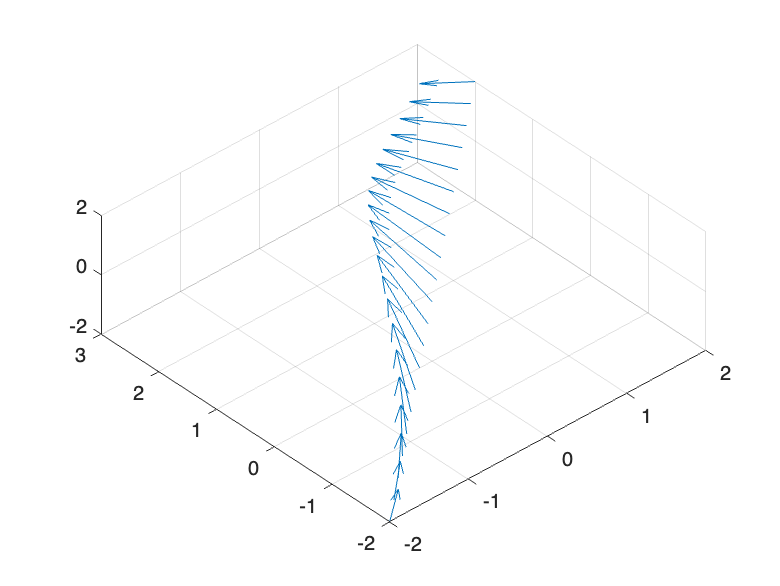

dl = 0.2;
x = -2:dl:2;
Lx = length(x); % = 20
y = x;
z = x;
Ly = Lx;
Lz = Lx;
N = 24;
d0 = (2*pi)/N;
theta = 0:d0:2*pi;
R = 1;
dy = R*d0*cos(theta);
dx = R*d0*sin(theta);
z0 = 0;
Pz(1:N) = z0;
Px = R*cos(theta);
Py = R*sin(theta);
rw = 0.1;

dBx(1:Lx,1:Ly,1:Lz) = 0;
dBy = dBx;
dBz = dBx;

I = 10; %Ampers
miu = 4*pi*1e-7; % 4*pi*(10^-7)
km = (miu*I) / (4*pi);

for i=1:Lx
    for j=1:Ly
        for k=1:Lz
            for n=1:N
                rx = x(i) - Px(n);
                ry = y(j) - Py(n);
                rz = z(k) - Pz(n);
                r = sqrt(rx.^2 + ry.^2 + rz.^2 + rw.^2);
                r3 = r^3;
                
                dBx(i,j,k) = dBx(i,j,k) + (km*dy(n)*rz) / r3;
                dBy(i,j,k) = dBy(i,j,k) + (km*dx(n)*rz) / r3;
                dBz(i,j,k) = dBz(i,j,k) + (km * ((dx(n)*ry - dy(n)*rx) / r3));
            end
        end
    end
end

B = sqrt(dBx.^2 + dBy.^2 + dBz.^2);
xx = dBx./B;
yy = dBy./B;
zz = dBz./B;


quiver3(x,y,z,dBx(1:Lx),dBy(1:Ly),dBz(1:Lz));